close all;
clear;
clc;


Rod is composed of N+1 rigid links joined by N flexible joints. Each joint has 2Dof for bending (ignoring extensions, shear and twist of the rod) The deformation of a simgle rod may be described by the rotation angles $\theta_1(k)$ and $\theta_2(k)$. $\theta_1(k)$ is the yaw angle (rotation around the z-axis). $\theta_2(k)$ is the pitch angle (rotate the y-axis by $\theta_1(k)$ first, $\theta_2(k)$ is then the rotation angle around the rotated y-axis).

The rod kinematics can be described as the poses of the discrete links along with the arc length.

The deformation of a single rod can be descrobed by the following equation:


$$\theta_i(k) = \sum^k_{n=1} \kappa_i(n), i=1,2$$


where kappa_i(n) is the curvature of the link n. The position of the distal end of the link n=k can be described:


$$\bf{p} = \pmatrix {\sum^k_{n=1} c\theta_2(n)c\theta_1(n)l(n)  \cr \sum^k_{n=1} c\theta_2(n)s\theta_1(n)l(n) \cr \sum^k_{n=1} s\theta_2(n)l(n)}$$


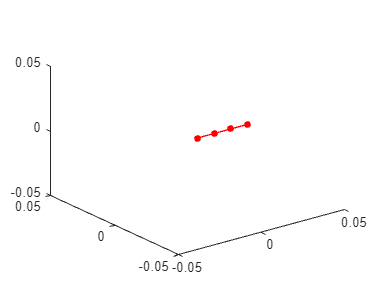

% kinematics test

% Define number of links
n = 3;
l = 0.01;

T11 =0;
T21 =0;
T12 =0;
T22 =0;
T13 =0;
T23 =0;

%Joint1
T1_1 = deg2rad(T11);
T2_1 = deg2rad(T21);

%Joint2
T1_2 = deg2rad(T12);
T2_2 = deg2rad(T22);

%Joint3
T1_3 = deg2rad(T13);
T2_3 = deg2rad(T23);

p(:,1) = [cos(T2_1)*cos(T1_1)*l
        cos(T2_1)*sin(T1_1)*l
        sin(T2_1)*l];

p(:,2) = p(:,1) + [cos(T2_2)*cos(T1_2)*l
       cos(T2_2)*sin(T1_2)*l
       sin(T2_2)*l];

p(:,3) = p(:,2) + [cos(T2_3)*cos(T1_3)*l
        cos(T2_3)*sin(T1_3)*l
        sin(T2_3)*l];



plot3([0,p(1,1),p(1,2),p(1,3)],[0,p(2,1),p(2,2),p(2,3)],[0,p(3,1),p(3,2),p(3,3)],...
    'ro-', 'MarkerSize', 4, 'MarkerFaceColor', 'r','LineWidth', 1);
axis([-0.05 0.05 -0.05 0.05 -0.05 0.05]);